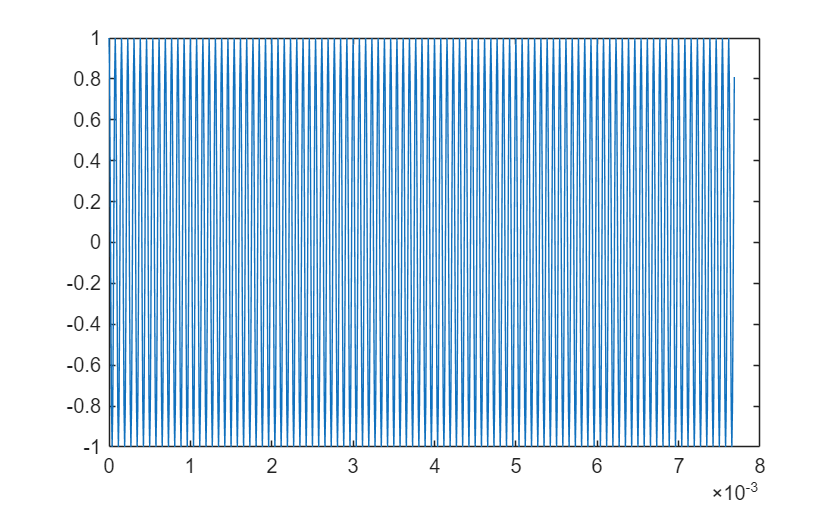

carrier_frequency = 13000; %hz
audio_frequency = 500; %hz
sampling_frequency = 10*carrier_frequency;
sampling_interval = 1/sampling_frequency;
L = 1e3;

t = (0:(L-1))*sampling_interval;
carrier_wave = cos(2*pi*carrier_frequency*t);
plot(t, carrier_wave)

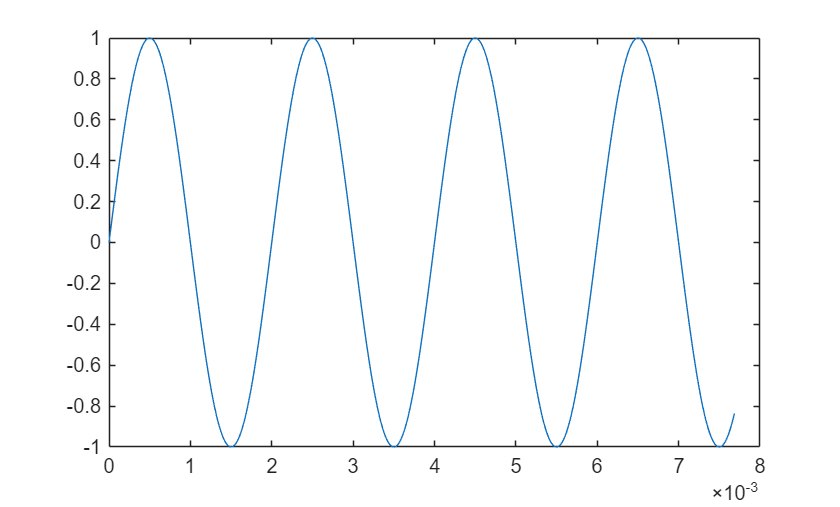

audio_wave = sin(2*pi*audio_frequency*t);
plot(t, audio_wave)

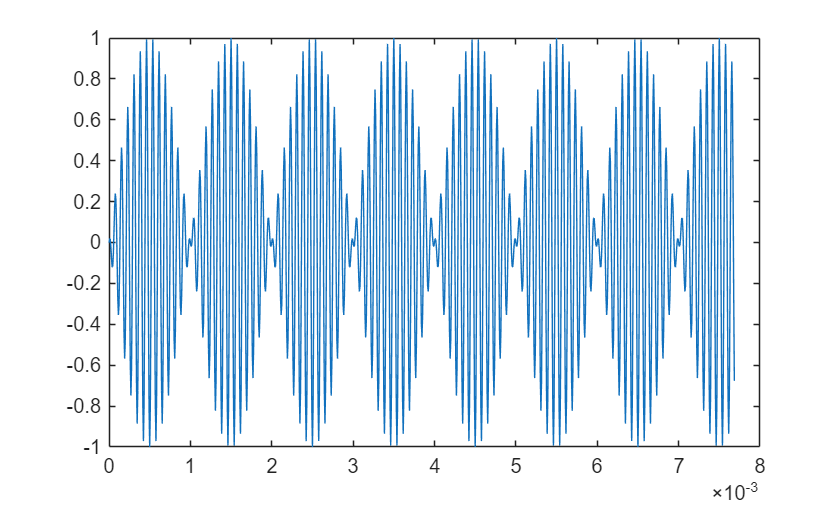

modulated_wave = audio_wave.*carrier_wave;
plot(t, modulated_wave)

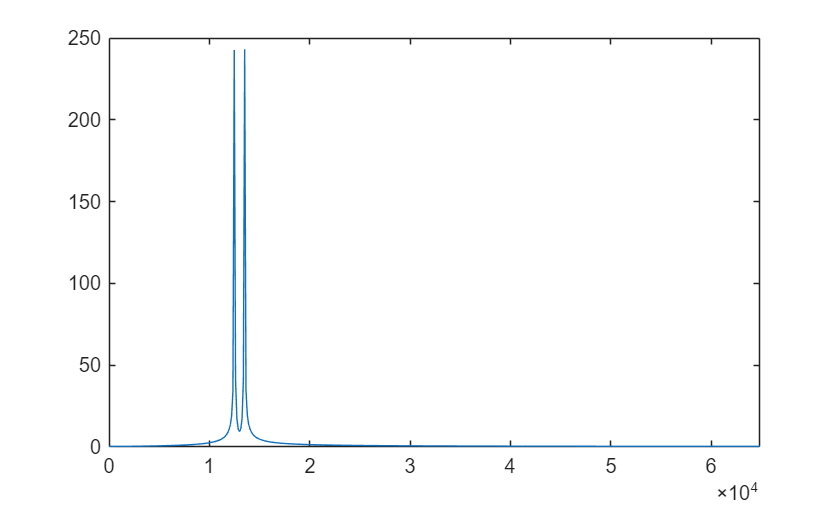

frequency_spectrum = fft(modulated_wave);
magnitude_spectrum = abs(frequency_spectrum);
shifted_spectrum = fftshift(magnitude_spectrum);
frequency = sampling_frequency/L*(-L/2:L/2-1);

plot(frequency, shifted_spectrum);
xlim([0, Inf]);

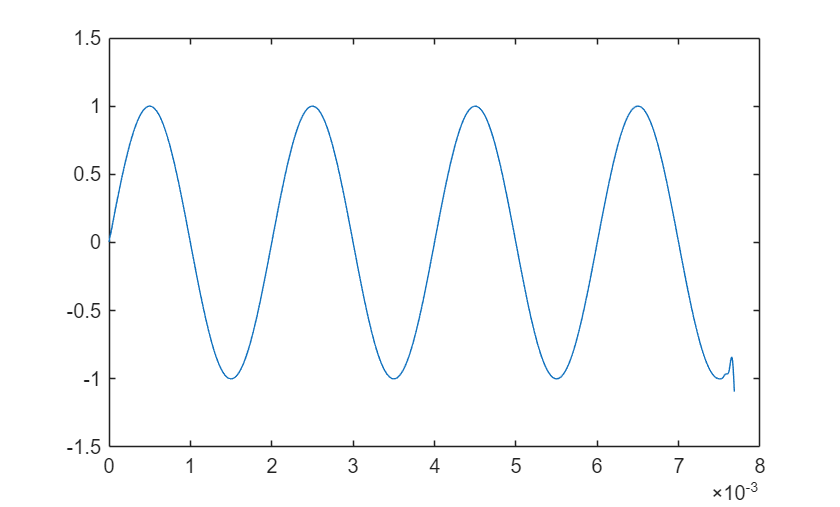

demodulated = amdemod(modulated_wave, carrier_frequency, sampling_frequency);
plot(t, demodulated)